# Exam 2017

## Problem 1: Linear Phase Filter

Linear phase filters with the symmetry property are commonly applied in audio signal processing due to their frequency independent group delay.

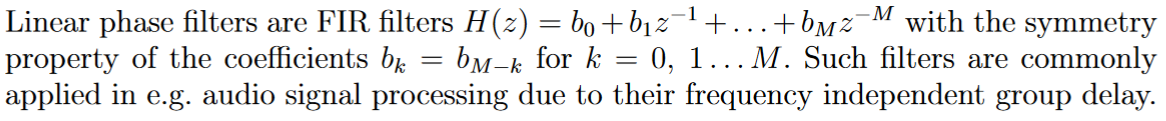

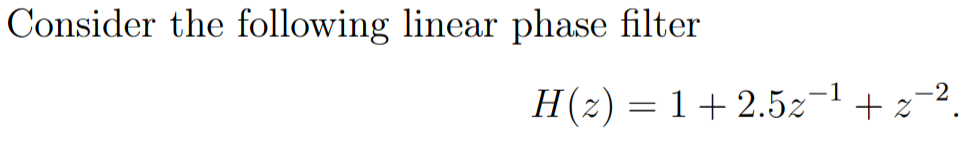

### 1) Rewrite the system function as a product of a minimum phase filter and an all-pass filter

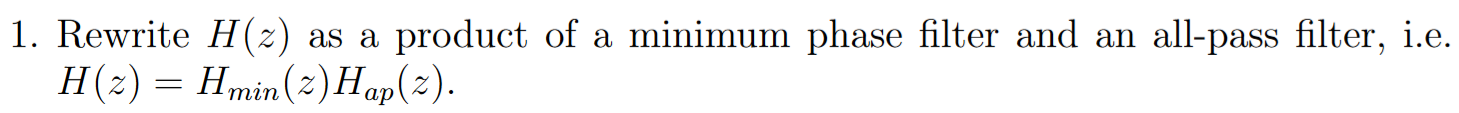

Any system function can be decomposed into a product of a minimum-phase filter and an all-pass filter using the following formula:

    
$$H\left(z\right)=H_{\mathrm{min}} \left(z\right)H_{\mathrm{ap}} \left(z\right)$$
  

The minimum phase filter can be computed as follows:

    
$$H_{\min } \left(z\right)=\prod_i \;-\frac{1}{{a_i }^* }H_i \left(z\right)\left(1-a_i z^{-1} \right)$$


where $H_i \left(z\right)$ corresponds to the part of the transfer function where the i'th zero is inside the unit circle and $a_i =\frac{1}{{z_i }^* }$ and $z_i$ is the zero outside the unit circle.

The allpass filter can be calculated:

    
$$H_{\textrm{ap}} \left(z\right)=z^{-N} \frac{1+a_1^* z+\cdots +a_N^* z^N }{1+a_1 z^{-1} +\cdots +a_N z^{-N} }$$


The filter decomposition algorithm has following steps:

- convert transfer function into pole-zero representation in order to find the zeros that are outside the unit circle

- compute $a$ and its conjugate $a^*$

- find $H_1 \left(z\right)$ which corresponds to the part of the transfer function where zeros are inside the unit circle

- plugin the numbers for the formula for the minimum-phase filter

- plugin the numbers for the formula for the allpass filter 

- put everything together:

These steps are coded in MATLAB function (see at the end of the document):


h = [1, -3, 5/2, -1];
[H_min, H_ap] = decompose_min_ap(h)
H_min * H_ap

syms z;

$$H\_min = \frac{3}{z}-\frac{2}{z^{2}}+\frac{1}{2\,z^{3}}-2$$

$$H\_ap = \frac{\frac{z}{2}+1}{z\,\left(\frac{1}{2\,z}+1\right)}$$

H = 1 + 5/2*z^(-1) + 2*z^(-2)

$$ans = \frac{\left(\frac{z}{2}+1\right)\,\left(\frac{3}{z}-\frac{2}{z^{2}}+\frac{1}{2\,z^{3}}-2\right)}{z\,\left(\frac{1}{2\,z}+1\right)}$$

h = filter_coeff(H, z)

# Functions

function [h]=filter_coeff(rational_system_expr, z)
    h = coeffs(expand(rational_system_expr * z^10), 'all');
    h = h(1:find(h, 1, 'last'));

$$H = \frac{5}{2\,z}+\frac{2}{z^{2}}+1$$

end

h = 1×3 cell array
    {1×1 sym}    {1×1 sym}    {1×1 sym}



function [H_min, H_ap]=decompose_min_ap(h)
    % Decomposes a filter into minimum-phase filter and all-pass filter
    %  h: the filter coefficients
    syms z;
    
    % Step 1
    rts = roots(h);
    
    H_outside = 1; % Represents part of H where zeros are outside the unit circle
    H_inside = 1;  % Represents part of H where zeros are inside the unit circle
    zeros_outside = [];
    for i = 1:numel(rts)
        root = rts(i);
        if abs(root) > 1
            H_outside = H_outside * (1 - root*z^-1);
            zeros_outside = [zeros_outside; root];
        else
            H_inside = H_inside * (1 - root*z^-1);
        end
    end

    % Sanity check
    % H = expand(H_inside * H_outside)
    % h_outside = filter_coeff(H_outside, z)
    % h_inside = filter_coeff(H_inside, z)
    
    % Compute minimum-phase filter and all-pass filter
    H_min = 1;
    H_ap_num = 1;
    H_ap_denom = 1;
    N = numel(zeros_outside);
    for i = 1:N
        z_i = zeros_outside(i);
        a = 1/z_i;
        a_conj = conj(a);
        H_min = H_min * (-(1/a_conj) * H_inside * (1-a * z^(-1)));
        H_ap_num =   H_ap_num + a_conj*z^i;
        H_ap_denom = H_ap_denom + a*z^(-i);
    end
    H_min = expand(H_min);
    
    % Compute all-pass filter
    H_ap = z^(-N) * (expand(H_ap_num) / expand(H_ap_denom));
    H_ap = H_ap;
end